# Read msgs

bag_detection=rosbag('../../../dataset/191116/2-2019-11-16-14-52-45-detection.bag');

term=[bag_detection.StartTime bag_detection.EndTime];
term1=[1573943760.111329 1573943822.538092];
time_extracted=term;

sbag_detection_mks_tracker=select(bag_detection,'Time',time_extracted,'Topic','/mks/detection/object_tracker/objects');
msgs_mks_tracker=readMessages(sbag_detection_mks_tracker);


## Get pedestrian objects

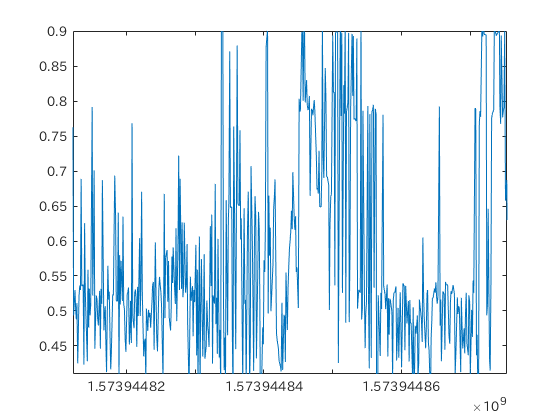

% time_mks_detector=sbag_detection_mks_tracker.MessageList{:,1};
% boolean_mks_detector_term1=time_mks_detector>term1(1) & time_mks_detector<term1(2);

s=length(msgs_mks_tracker);
msgs_mks_pedestrian=rosmessage('autoware_msgs/DetectedObject');
for i=1:s
    objects=msgs_mks_tracker{i}.Objects;
    msgs_mks_pedestrian(i)=rosmessage('autoware_msgs/DetectedObject');
    for j=1:length(objects)
        if strcmp(objects(j).Label,'pedestrian')
            msgs_mks_pedestrian(i)=objects(j);
        end
    end
end

mks_pedestrian_dimension=zeros(s,3);
for i=1:s
    mks_pedestrian_dimension(i,:)=[msgs_mks_pedestrian(i).Dimensions.X ...
                                   msgs_mks_pedestrian(i).Dimensions.Y...
                                   msgs_mks_pedestrian(i).Dimensions.Z];
end

time_mks_tracker=sbag_detection_mks_tracker.MessageList{:,1};
plot(time_mks_tracker,mks_pedestrian_dimension(:,1));